clear; clc; close all;

% Tambahkan folder package ke path
addpath('/MATLAB Drive/MS_Regress-Matlab-master/m_Files');

% =========================================================
% BACA DATA
% =========================================================
dataTbl = readtable('/MATLAB Drive/fix_dataset_insyaAllah.csv');
dataTbl.Date = datetime(dataTbl.Date);

% Ambil kolom return
% Urutan variabel: [IHSG, Gold, BTC]
Yraw = [double(dataTbl.ihsg), double(dataTbl.gold), double(dataTbl.btc)];

% Hapus baris yang mengandung NaN / Inf
idxValid = all(isfinite(Yraw), 2);
Y     = Yraw(idxValid, :);
dates = dataTbl.Date(idxValid);

% =========================================================
% SPESIFIKASI DASAR
% =========================================================
dep_raw = Y;

% Ubah bagian ini kalau ingin VAR(5), VAR(3), dst.
nLag = 1;

% Jumlah rezim
k = 2;

[nT, nVar] = size(dep_raw);

if nVar ~= 3
    error('Y harus memiliki 3 kolom: [ihsg gold btc]');
end

if nT <= nLag
    error('Jumlah observasi terlalu sedikit untuk nLag = %d.', nLag);
end

% =========================================================
% MEMBENTUK DEPENDENT DAN LAG VAR
% =========================================================
dep       = dep_raw(nLag+1:end, :);   % Y_t
dates_eff = dates(nLag+1:end);        % tanggal efektif
nObs      = size(dep,1);

% Matriks lag:
% Jika nLag = 1:
% [ihsg(-1), gold(-1), btc(-1)]
%
% Jika nLag = 5:
% [ihsg(-1), gold(-1), btc(-1), ..., ihsg(-5), gold(-5), btc(-5)]
Xlag = [];

for L = 1:nLag
    Xlag = [Xlag dep_raw(nLag+1-L:end-L, :)];
end

% Regressor:
% [const, seluruh lag VAR]
X = [ones(nObs,1), Xlag];

% Input independen untuk setiap persamaan
indep = cell(1, nVar);

for eq = 1:nVar
    indep{eq} = X;
end

% Jumlah regressor otomatis:
% nReg = 1 konstanta + nVar*nLag
nReg = size(X,2);
expectedReg = 1 + nVar*nLag;

if nReg ~= expectedReg
    error('Jumlah regressor tidak sesuai. Harus %d, tetapi terbentuk %d.', ...
        expectedReg, nReg);
end

fprintf('\n=========================================================\n');

fprintf('INFORMASI SPESIFIKASI MODEL\n');

INFORMASI SPESIFIKASI MODEL


fprintf('=========================================================\n');

fprintf('Jumlah variabel        : %d\n', nVar);

Jumlah variabel        : 3


fprintf('Jumlah lag VAR         : %d\n', nLag);

Jumlah lag VAR         : 1


fprintf('Jumlah observasi awal  : %d\n', nT);

Jumlah observasi awal  : 2346


fprintf('Jumlah observasi efektif: %d\n', nObs);

Jumlah observasi efektif: 2345


fprintf('Jumlah regressor       : %d\n', nReg);

Jumlah regressor       : 4


fprintf('Panjang S vector       : %d\n', nReg + 1);

Panjang S vector       : 5



% =========================================================
% ADVANCED OPTIONS
% =========================================================
advOpt.distrib    = 'Normal';
advOpt.std_method = 1;
advOpt.diagCovMat = 0;      % 0 = full variance-covariance matrix
advOpt.printOut   = 1;
advOpt.printIter  = 1;
advOpt.doPlots    = 1;
advOpt.optimizer  = 'fminsearch';

% =========================================================
% DAFTAR MODEL MS-VAR YANG AKAN DICOBA
%
% Struktur S vector:
% Jika nLag = 1 dan nVar = 3:
% [intercept, ihsg(-1), gold(-1), btc(-1), covariance]
%
% Jika nLag = 5 dan nVar = 3:
% [intercept, 15 koefisien lag VAR, covariance]
%
% Elemen terakhir = variance-covariance switching
% =========================================================
modelList = struct();

% 1) Linear VAR: tidak ada switching
modelList(1).name = 'linear VAR';
modelList(1).desc = 'Tidak ada parameter yang switching';
modelList(1).interceptSwitch = 0;
modelList(1).ARSwitch        = 0;
modelList(1).covSwitch       = 0;

% 2) MSH-VAR: hanya H switching
modelList(2).name = 'MSH-VAR';
modelList(2).desc = 'Hanya variance-covariance switching';
modelList(2).interceptSwitch = 0;
modelList(2).ARSwitch        = 0;
modelList(2).covSwitch       = 1;

% 3) MSI-VAR: hanya I switching
modelList(3).name = 'MSI-VAR';
modelList(3).desc = 'Hanya intercept switching';
modelList(3).interceptSwitch = 1;
modelList(3).ARSwitch        = 0;
modelList(3).covSwitch       = 0;

% 4) MSIH-VAR: I + H switching
modelList(4).name = 'MSIH-VAR';
modelList(4).desc = 'Intercept + variance-covariance switching';
modelList(4).interceptSwitch = 1;
modelList(4).ARSwitch        = 0;
modelList(4).covSwitch       = 1;

% 5) MSA-VAR: hanya A switching
modelList(5).name = 'MSA-VAR';
modelList(5).desc = 'Hanya koefisien autoregressive switching';
modelList(5).interceptSwitch = 0;
modelList(5).ARSwitch        = 1;
modelList(5).covSwitch       = 0;

% 6) MSAH-VAR: A + H switching
modelList(6).name = 'MSAH-VAR';
modelList(6).desc = 'Koefisien autoregressive + variance-covariance switching';
modelList(6).interceptSwitch = 0;
modelList(6).ARSwitch        = 1;
modelList(6).covSwitch       = 1;

% 7) MSIA-VAR: I + A switching
modelList(7).name = 'MSIA-VAR';
modelList(7).desc = 'Intercept + koefisien autoregressive switching';
modelList(7).interceptSwitch = 1;
modelList(7).ARSwitch        = 1;
modelList(7).covSwitch       = 0;

% 8) MSIAH-VAR: I + A + H switching
modelList(8).name = 'MSIAH-VAR';
modelList(8).desc = 'Intercept + koefisien autoregressive + variance-covariance switching';
modelList(8).interceptSwitch = 1;
modelList(8).ARSwitch        = 1;
modelList(8).covSwitch       = 1;

nModels = numel(modelList);

% =========================================================
% ESTIMASI SEMUA MODEL
% =========================================================
Results = struct();
summaryCell = cell(nModels, 8);

fprintf('\n=========================================================\n');

fprintf('ESTIMASI SELURUH MODEL MS-VAR\n');

ESTIMASI SELURUH MODEL MS-VAR


fprintf('=========================================================\n');


----------------------------------------


Estimasi linear VAR


Tidak ada parameter yang switching


S = [0  0  0  0  0]


GAGAL | The S input should have at least one value 1 in each equation (something must switch states).



----------------------------------------


Estimasi MSH-VAR


Hanya variance-covariance switching


S = [0  0  0  0  1]



Sum log likelihood for MS Model -> -12334.5702
Sum log likelihood for MS Model -> -12346.0129
Sum log likelihood for MS Model -> -12334.5468
Sum log likelihood for MS Model -> -12342.5037
Sum log likelihood for MS Model -> -12334.6001
Sum log likelihood for MS Model -> -12334.568
Sum log likelihood for MS Model -> -12344.3894
Sum log likelihood for MS Model -> -12322.9083
Sum log likelihood for MS Model -> -12334.5925
Sum log likelihood for MS Model -> -12325.8351
Sum log likelihood for MS Model -> -12334.5808
Sum log likelihood for MS Model -> -12334.5728
Sum log likelihood for MS Model -> -12324.1143
Sum log likelihood for MS Model -> -12334.5547
Sum log likelihood for MS Model -> -12334.5809
Sum log likelihood for MS Model -> -12334.5735
Sum log likelihood for MS Model -> -12334.582
Sum log likelihood for MS Model -> -12334.6355
Sum log likelihood for MS Model -> -12334.5766
Sum log likelihood for MS Model -> -12334.584
Sum log likelihood for MS Model -> -12334.6562
Sum log likelih

SUKSES | LL = -11763.8985 | AIC = 23579.7971 | BIC = 23758.1221



----------------------------------------


Estimasi MSI-VAR


Hanya intercept switching


S = [1  0  0  0  0]



Sum log likelihood for MS Model -> -12693.1112
Sum log likelihood for MS Model -> -12675.9465
Sum log likelihood for MS Model -> -12693.1389
Sum log likelihood for MS Model -> -12677.184
Sum log likelihood for MS Model -> -12693.6141
Sum log likelihood for MS Model -> -12693.1138
Sum log likelihood for MS Model -> -12676.4629
Sum log likelihood for MS Model -> -12693.0978
Sum log likelihood for MS Model -> -12692.8958
Sum log likelihood for MS Model -> -12693.1093
Sum log likelihood for MS Model -> -12693.1135
Sum log likelihood for MS Model -> -12693.1107
Sum log likelihood for MS Model -> -12693.1246
Sum log likelihood for MS Model -> -12693.1086
Sum log likelihood for MS Model -> -12693.0877
Sum log likelihood for MS Model -> -12693.2304
Sum log likelihood for MS Model -> -12693.1171
Sum log likelihood for MS Model -> -12693.1257
Sum log likelihood for MS Model -> -12693.1221
Sum log likelihood for MS Model -> -12693.0759
Sum log likelihood for MS Model -> -12693.1257
Sum log likel

SUKSES | LL = -12496.7879 | AIC = 25045.5758 | BIC = 25223.9007



----------------------------------------


Estimasi MSIH-VAR


Intercept + variance-covariance switching


S = [1  0  0  0  1]



Sum log likelihood for MS Model -> -12347.1861
Sum log likelihood for MS Model -> -12358.6983
Sum log likelihood for MS Model -> -12347.1652
Sum log likelihood for MS Model -> -12354.7778
Sum log likelihood for MS Model -> -12347.2163
Sum log likelihood for MS Model -> -12347.1846
Sum log likelihood for MS Model -> -12356.8788
Sum log likelihood for MS Model -> -12335.2921
Sum log likelihood for MS Model -> -12347.2082
Sum log likelihood for MS Model -> -12338.0372
Sum log likelihood for MS Model -> -12347.2055
Sum log likelihood for MS Model -> -12347.189
Sum log likelihood for MS Model -> -12336.5067
Sum log likelihood for MS Model -> -12347.1995
Sum log likelihood for MS Model -> -12347.1884
Sum log likelihood for MS Model -> -12347.2027
Sum log likelihood for MS Model -> -12347.1829
Sum log likelihood for MS Model -> -12347.1955
Sum log likelihood for MS Model -> -12347.2999
Sum log likelihood for MS Model -> -12347.1878
Sum log likelihood for MS Model -> -12347.2008
Sum log likel

SUKSES | LL = -11760.7438 | AIC = 23579.4876 | BIC = 23778.3885



----------------------------------------


Estimasi MSA-VAR


Hanya koefisien autoregressive switching


S = [0  1  1  1  0]



Sum log likelihood for MS Model -> -12688.425
Sum log likelihood for MS Model -> -12671.4177
Sum log likelihood for MS Model -> -12688.4346
Sum log likelihood for MS Model -> -12673.1438
Sum log likelihood for MS Model -> -12688.8568
Sum log likelihood for MS Model -> -12688.4258
Sum log likelihood for MS Model -> -12672.1005
Sum log likelihood for MS Model -> -12688.4419
Sum log likelihood for MS Model -> -12688.189
Sum log likelihood for MS Model -> -12688.4299
Sum log likelihood for MS Model -> -12688.4254
Sum log likelihood for MS Model -> -12688.4281
Sum log likelihood for MS Model -> -12688.4296
Sum log likelihood for MS Model -> -12688.3717
Sum log likelihood for MS Model -> -12688.4053
Sum log likelihood for MS Model -> -12688.4207
Sum log likelihood for MS Model -> -12688.4254
Sum log likelihood for MS Model -> -12688.274
Sum log likelihood for MS Model -> -12688.5022
Sum log likelihood for MS Model -> -12688.3575
Sum log likelihood for MS Model -> -12688.4133
Sum log likelih

SUKSES | LL = -12480.0968 | AIC = 25024.1935 | BIC = 25243.6704



----------------------------------------


Estimasi MSAH-VAR


Koefisien autoregressive + variance-covariance switching


S = [0  1  1  1  1]



Sum log likelihood for MS Model -> -12381.0547
Sum log likelihood for MS Model -> -12392.1209
Sum log likelihood for MS Model -> -12381.031
Sum log likelihood for MS Model -> -12388.3276
Sum log likelihood for MS Model -> -12381.1057
Sum log likelihood for MS Model -> -12381.0514
Sum log likelihood for MS Model -> -12390.3119
Sum log likelihood for MS Model -> -12369
Sum log likelihood for MS Model -> -12381.0711
Sum log likelihood for MS Model -> -12371.3169
Sum log likelihood for MS Model -> -12381.0823
Sum log likelihood for MS Model -> -12381.0575
Sum log likelihood for MS Model -> -12370.3852
Sum log likelihood for MS Model -> -12381.0395
Sum log likelihood for MS Model -> -12381.1129
Sum log likelihood for MS Model -> -12381.0442
Sum log likelihood for MS Model -> -12381.0836
Sum log likelihood for MS Model -> -12381.1104
Sum log likelihood for MS Model -> -12381.0605
Sum log likelihood for MS Model -> -12381.063
Sum log likelihood for MS Model -> -12381.0067
Sum log likelihood 

SUKSES | LL = -11763.5125 | AIC = 23597.0250 | BIC = 23837.0778



----------------------------------------


Estimasi MSIA-VAR


Intercept + koefisien autoregressive switching


S = [1  1  1  1  0]



Sum log likelihood for MS Model -> -12698.0845
Sum log likelihood for MS Model -> -12681.0769
Sum log likelihood for MS Model -> -12698.1037
Sum log likelihood for MS Model -> -12682.7974
Sum log likelihood for MS Model -> -12698.5992
Sum log likelihood for MS Model -> -12698.0862
Sum log likelihood for MS Model -> -12681.928
Sum log likelihood for MS Model -> -12698.0857
Sum log likelihood for MS Model -> -12697.7449
Sum log likelihood for MS Model -> -12698.0867
Sum log likelihood for MS Model -> -12698.0657
Sum log likelihood for MS Model -> -12698.1115
Sum log likelihood for MS Model -> -12698.0386
Sum log likelihood for MS Model -> -12698.0708
Sum log likelihood for MS Model -> -12698.0795
Sum log likelihood for MS Model -> -12698.0849
Sum log likelihood for MS Model -> -12697.9491
Sum log likelihood for MS Model -> -12698.1655
Sum log likelihood for MS Model -> -12697.6171
Sum log likelihood for MS Model -> -12698.4843
Sum log likelihood for MS Model -> -12698.0395
Sum log likel

SUKSES | LL = -12463.2598 | AIC = 24996.5197 | BIC = 25236.5725



----------------------------------------


Estimasi MSIAH-VAR


Intercept + koefisien autoregressive + variance-covariance switching


S = [1  1  1  1  1]



Sum log likelihood for MS Model -> -12393.3684
Sum log likelihood for MS Model -> -12404.4439
Sum log likelihood for MS Model -> -12393.3474
Sum log likelihood for MS Model -> -12400.2928
Sum log likelihood for MS Model -> -12393.4166
Sum log likelihood for MS Model -> -12393.3659
Sum log likelihood for MS Model -> -12402.4871
Sum log likelihood for MS Model -> -12381.1123
Sum log likelihood for MS Model -> -12393.3848
Sum log likelihood for MS Model -> -12383.2688
Sum log likelihood for MS Model -> -12393.4091
Sum log likelihood for MS Model -> -12393.3713
Sum log likelihood for MS Model -> -12382.5264
Sum log likelihood for MS Model -> -12393.3053
Sum log likelihood for MS Model -> -12393.353
Sum log likelihood for MS Model -> -12393.3997
Sum log likelihood for MS Model -> -12393.4237
Sum log likelihood for MS Model -> -12393.3768
Sum log likelihood for MS Model -> -12393.3793
Sum log likelihood for MS Model -> -12393.3255
Sum log likelihood for MS Model -> -12393.5323
Sum log likel

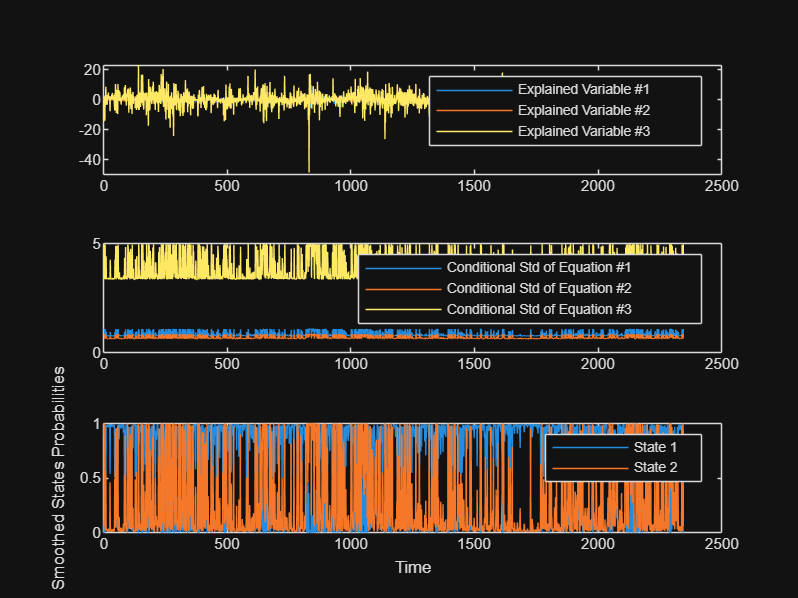

SUKSES | LL = -11763.2377 | AIC = 23602.4754 | BIC = 23863.1042



for m = 1:nModels

    % -----------------------------------------------------
    % Bangun vektor switching dasar secara otomatis
    %
    % Panjang Svec = nReg + 1
    % nReg        = jumlah regressor, termasuk intercept
    % elemen 1    = intercept
    % elemen 2:nReg = koefisien lag VAR
    % elemen nReg+1 = variance-covariance switching
    % -----------------------------------------------------
    Svec = zeros(1, nReg + 1);

    % Intercept switching
    Svec(1) = modelList(m).interceptSwitch;

    % AR coefficients switching
    if modelList(m).ARSwitch == 1
        Svec(2:nReg) = 1;
    else
        Svec(2:nReg) = 0;
    end

    % Covariance switching
    Svec(nReg + 1) = modelList(m).covSwitch;

    % Salin S vector ke semua persamaan
    S = cell(1, nVar);

    for eq = 1:nVar
        S{eq} = Svec;
    end

    fprintf('\n----------------------------------------\n');
    fprintf('Estimasi %s\n', modelList(m).name);
    fprintf('%s\n', modelList(m).desc);
    fprintf('S = [%s]\n', num2str(Svec));

    try
        Spec = MS_Regress_Fit(dep, indep, k, S, advOpt);

        Results(m).name = modelList(m).name;
        Results(m).desc = modelList(m).desc;
        Results(m).S    = Svec;
        Results(m).Spec = Spec;
        Results(m).LL   = Spec.LL;
        Results(m).AIC  = Spec.AIC;
        Results(m).BIC  = Spec.BIC;
        Results(m).ok   = true;
        Results(m).err  = '';

        summaryCell{m,1} = modelList(m).name;
        summaryCell{m,2} = modelList(m).desc;
        summaryCell{m,3} = mat2str(Svec);
        summaryCell{m,4} = Spec.LL;
        summaryCell{m,5} = Spec.AIC;
        summaryCell{m,6} = Spec.BIC;
        summaryCell{m,7} = 'OK';
        summaryCell{m,8} = '';

        fprintf('SUKSES | LL = %.4f | AIC = %.4f | BIC = %.4f\n', ...
            Spec.LL, Spec.AIC, Spec.BIC);

    catch ME
        Results(m).name = modelList(m).name;
        Results(m).desc = modelList(m).desc;
        Results(m).S    = Svec;
        Results(m).Spec = [];
        Results(m).LL   = NaN;
        Results(m).AIC  = NaN;
        Results(m).BIC  = NaN;
        Results(m).ok   = false;
        Results(m).err  = ME.message;

        summaryCell{m,1} = modelList(m).name;
        summaryCell{m,2} = modelList(m).desc;
        summaryCell{m,3} = mat2str(Svec);
        summaryCell{m,4} = NaN;
        summaryCell{m,5} = NaN;
        summaryCell{m,6} = NaN;
        summaryCell{m,7} = 'GAGAL';
        summaryCell{m,8} = ME.message;

        fprintf('GAGAL | %s\n', ME.message);
    end
end


% =========================================================
% RINGKASAN HASIL
% =========================================================
SummaryTable = cell2table(summaryCell, ...
    'VariableNames', {'Model','Deskripsi','S_Vector','LL','AIC','BIC','Status','Catatan'});

fprintf('\n=========================================================\n');

fprintf('RINGKASAN HASIL ESTIMASI\n');

RINGKASAN HASIL ESTIMASI


fprintf('=========================================================\n');

disp(SummaryTable);

        Model                                        Deskripsi                                       S_Vector          LL       AIC      BIC      Status                                                   Catatan                                             
    ______________    ________________________________________________________________________    _______________    ______    _____    _____    _________    _________________________________________________________________________________________________

    {'linear VAR'}    {'Tidak ada parameter yang switching'                                  }    {'[0 0 0 0 0]'}       NaN      NaN      NaN    {'GAGAL'}    {'The S input should have at least one value 1 in each eq


% =========================================================
% PILIH MODEL TERBAIK BERDASARKAN AIC TERKECIL
% =========================================================
okArray = [Results.ok];
AICArray = [Results.AIC];

validIdx = find(okArray & isfinite(AICArray));

if isempty(validIdx)
    error('Tidak ada model yang berhasil diestimasi.');
end

allAIC = AICArray(validIdx);
[bestAIC, loc] = min(allAIC);
bestIdx = validIdx(loc);

BestModel = Results(bestIdx).Spec;
bestName  = Results(bestIdx).name;

fprintf('\n=========================================================\n');

fprintf('MODEL TERBAIK BERDASARKAN AIC\n');

MODEL TERBAIK BERDASARKAN AIC


fprintf('=========================================================\n');

fprintf('Model terbaik : %s\n', bestName);

Model terbaik : MSIH-VAR


fprintf('LL            : %.4f\n', Results(bestIdx).LL);

LL            : -11760.7438


fprintf('AIC           : %.4f\n', Results(bestIdx).AIC);

AIC           : 23579.4876


fprintf('BIC           : %.4f\n', Results(bestIdx).BIC);

BIC           : 23778.3885



% =========================================================
% URUTKAN MODEL BERDASARKAN AIC
% =========================================================
rankTable = SummaryTable(strcmp(SummaryTable.Status,'OK'), :);
rankTable = sortrows(rankTable, 'AIC', 'ascend');

fprintf('\n=========================================================\n');

fprintf('PERINGKAT MODEL BERDASARKAN AIC\n');

PERINGKAT MODEL BERDASARKAN AIC


fprintf('=========================================================\n');

disp(rankTable);

        Model                                       Deskripsi                                       S_Vector          LL       AIC      BIC     Status     Catatan  
    _____________    ________________________________________________________________________    _______________    ______    _____    _____    ______    __________

    {'MSIH-VAR' }    {'Intercept + variance-covariance switching'                           }    {'[1 0 0 0 1]'}    -11761    23579    23778    {'OK'}    {0×0 char}
    {'MSH-VAR'  }    {'Hanya variance-covariance switching'                                 }    {'[0 0 0 0 1]'}    -11764    23580    23758    {'OK'}    {0×0 char}
    {'MSAH-VAR' }    {'Koefisien autoregressive + variance-covarian


% =========================================================
% SIMPAN HASIL
% =========================================================
save('hasil_perbandingan_msvar_semua_model.mat', ...
     'Results', 'SummaryTable', 'rankTable', ...
     'BestModel', 'bestName', 'bestIdx', ...
     'dates_eff', 'dep', 'indep', 'X', 'Y', ...
     'k', 'nLag', 'nVar', 'nReg');

fprintf('\n=========================================================\n');

fprintf('HASIL BERHASIL DISIMPAN\n');

HASIL BERHASIL DISIMPAN


fprintf('File: hasil_perbandingan_msvar_semua_model.mat\n');

File: hasil_perbandingan_msvar_semua_model.mat


fprintf('=========================================================\n');